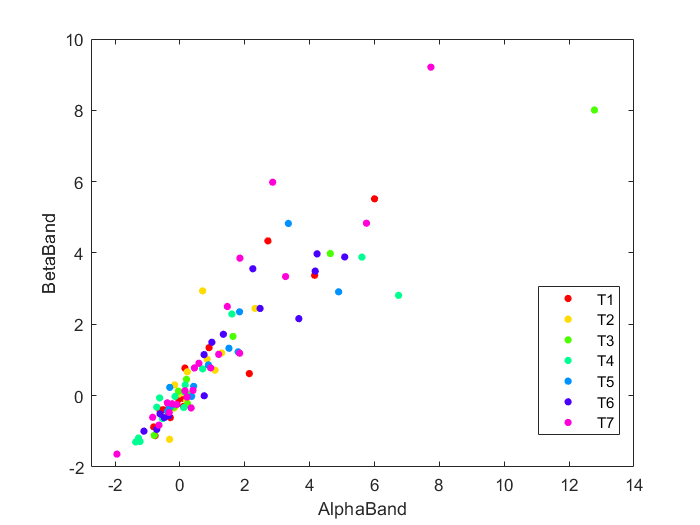

meas = squeeze(trLfpData_spec_feature(:, 243,:));

AlphaBand = trLfpData_spec_feature(:,1); %alpha band
BetaBand = trLfpData_spec_feature(:,2); %beta band

h1 = gscatter(AlphaBand,BetaBand,trial_TargetAssigned);

legend('T1','T2','T3','T4','T5','T6','T7',"Location",'best')

These features are not really separable! Are we overfitting with 8 features, 7 directions and over 100 trials?

MdlLinear = fitcdiscr(meas,trial_TargetAssigned,'DiscrimType',"pseudolinear", "Leaveout","on");
%grouphat = predict(MdlLinear,meas);
[grouphat,Predict_Scores] = kfoldPredict(MdlLinear)

grouphat = 102×1 uint8 column vector
   2
   7
   4
   7
   7
   7
   2
   6
   7
   6


Predict_Scores =     0.0000    0.9306    0.0004    0.0001    0.0000    0.0689    0.0000
    0.2015    0.0679    0.1250    0.0539    0.1455    0.0751    0.3311
    0.0002    0.0000    0.0001    0.9992    0.0002    0.0000    0.0003
    0.2048    0.0595    0.1259    0.0585    0.1501    0.0701    0.3311
    0.1978    0.0675    0.1262    0.0659    0.1386    0.0818    0.3222
    0.2527    0.1213    0.1223    0.0537    0.1044    0.0442    0.3014
    0.0015    0.9791    0.0130    0.0013    0.0002    0.0000    0.0049
    0.1210    0.0645    0.0862    0.1346    0.0996    0.3097    0.1844
    0.2077    0.0595    0.1273    0.0536    0.1509    0.0665    0.3345
    0.1096    0.0782    0.0599    0.1252    0.1968    0.2428    0.1876



C = confusionmat(trial_TargetAssigned,grouphat)

C =      0     1     0     0     0     1    13
     1     0     0     4     0     3     6
     0     1     0     1     0     0     7
     0     4     0     0     1     3     7
     0     0     0     1     0     0    11
     0     1     0     2     1     3     8
     0     0     0     1     0     1    20


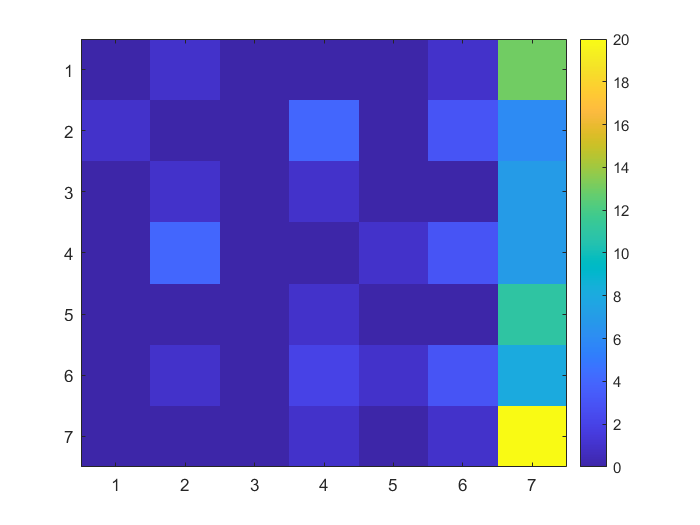

imagesc(C)
colorbar

are we overfitting the 

sum(trial_TargetAssigned == grouphat) / length(trial_TargetAssigned)

ans = 0.2255